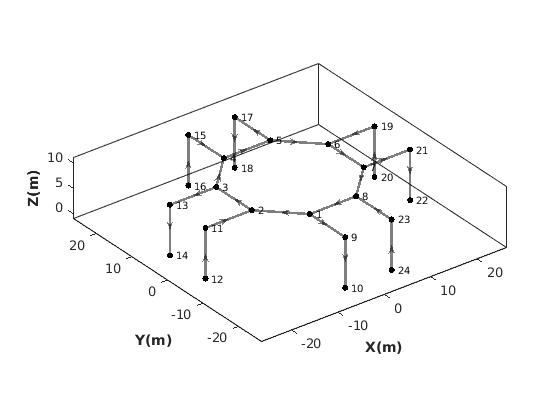

clear
clf
% Create a simulator object
sim = Sim();
% Disable Radar initialization, since this example uses
% a single lane on the ground
sim.en_init_radar = false;


% Define a single-lane LBSD object
lane_length_m = 500;
num_lanes = 1;
% lbsd = LBSD.genSimpleLanes(lane_length_m*ones(1,num_lanes));
lane_length_m = 10;
altitude_m = 10;
lbsd = LBSD.genSampleLanes(lane_length_m, altitude_m);
plot(lbsd);

sim.lbsd = lbsd;

% Initialize the uas configuration
uas_config = UASConfig();
uas_config.num_uas = 5;
uas_config.setSpeedMix('CONSTANT',1)
uas_config.setHeadwayMix('CONSTANT',10)
uas_config.setFlexMix('CONSTANT',100)

sim.uas_config = uas_config;

% initialize the simulation configuration
sim_config = SimConfig();
sim_config.t0 = 0;
sim_config.tf = 1000;

sim.sim_config = sim_config;

figure;
% h_lbsd = lbsd.plot();
% disp(lbsd.lane_graph.Nodes)
% disp(lbsd.lane_graph.Edges)

sim.initialize(true);

Checking if LBSD is Instantiated
Initializing ATOC
Initializing UAS Dataset
Initializing UAS Trajectories
Updating Metrics
Done


sim.reset()

Simulation Started


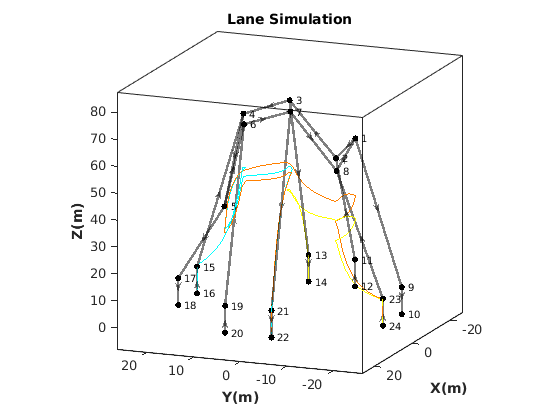

Simulation Complete


sim.run_sim()

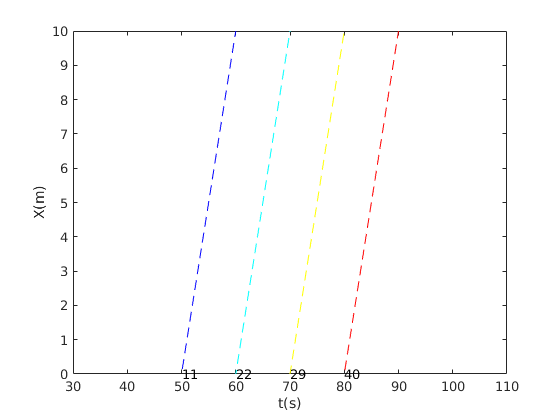

figure;
%sim.plotTrajsX();
lbsd.plotLaneDiagram("4");

min_hd = sim.getMaxXDeviation();
disp(["Max Deviation from Planned Trajectory = " min_hd])

    "Max Deviation from Planned Trajectory = "    "87.9289"



res = sim.lbsd.getReservations;
et = res.entry_time_s;
et = sort(et);
et_d = et(2:end)-et(1:end-1);
h_t = uas_config.hd_value/uas_config.speed_value;
all((et_d - h_t)>-100*eps)

ans = logical
   0


find((et_d - h_t)<-100*eps)

ans =      1
     3
     4
     6
     7
     9
    10
    11
    13
    14


sim.sim_metrics.lane_occs